# Eksamen M3DYN1-03 Dynamik

Besvarelsen er udført af

- Morten Erichsen

- AUID: au606069

- Studienr: 201807571

# Opgave 1

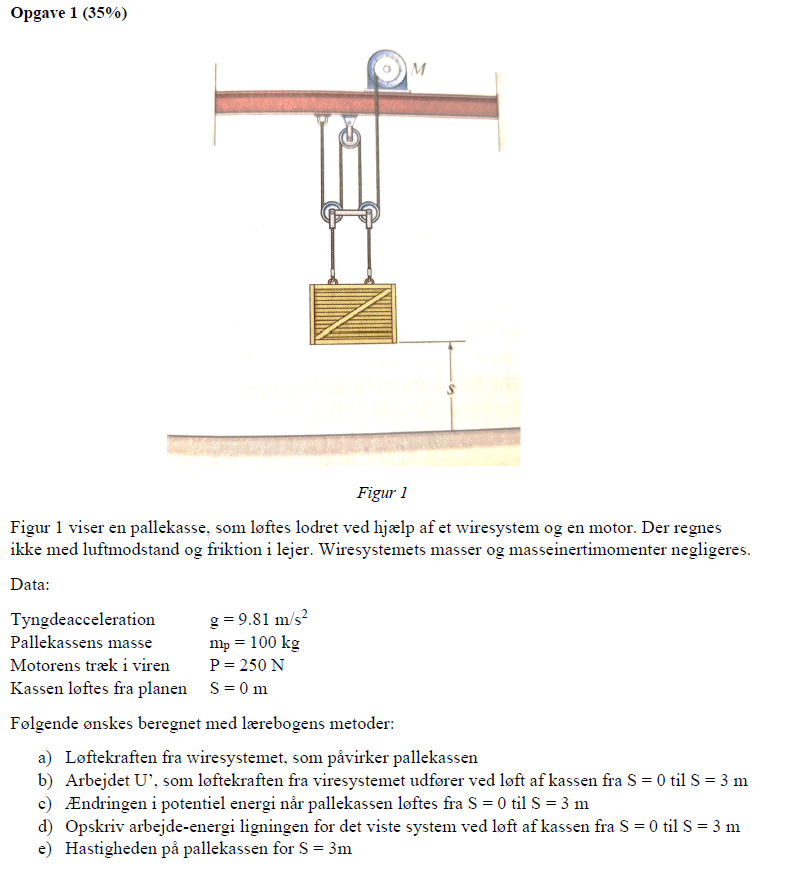

clear

% Data til opgaven
g = 9.81; % m/s^2
mp = 100; % kg 
P = 250;  % Newton
S = 0;    % m

## Opgave a)

Løftekraften som wiresystemet skal overvinde, er lige så stor som den kraft kassen trækker ned med

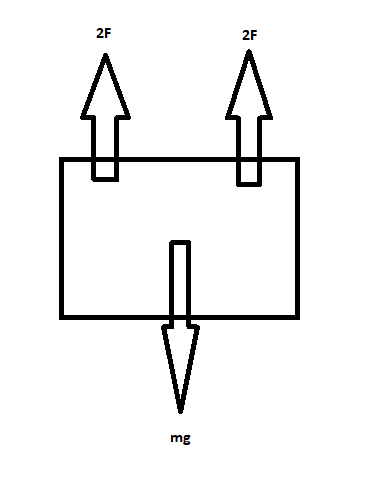

Det ses ud fra FLD at der trækkes med en faktor 4 større end der "trækkes" ned med, så løftekraften bliver


$$\sum F_y = 0
\\
4F  - mg = 0
\\
F = \frac{1}{4}mg$$


F = 1/4 * mp * g

F = 245.2500


% Da wiren trækker med P, bliver den totale løftekraft
F_k = P - F

F_k = 4.7500

Svar til opgave a:

Den overskydende kraft motoren påfører kassen, efter kassens tyngekraftsbidrag på 245,25N er overvundet


$$F_k = P - F = 4,75N$$


## Opgave b)

Arbejdet er resultatet af den flytning som kassen oplever


$$U_{1-2} =F_k \cdot (y_2 - y1)\\$$


Her trækkes den kraft der skal overvindes fra motorens træk i wiren, da den resterende kraft er hvad kassen oplever, og hvad der giver anledning til den bevæger sig opad

y1 = 0;
y2 = 3; % meter

U12 = F_k*(y2-y1)

U12 = 14.2500

Svar til opgave b


$$U_{1-2} = (P-F_k) \cdot (y_2 - y1) = 14,25\cdot Nm$$


## Opgave c)

Til at starte med er kassen i en højde af 0m, og flyttes til 3m

h1 = 0; % Samme som y0 og y2
h2 = 3;

U1 = mp*g*h1

U1 = 0

U2 = -mp*g*h2

U2 = -2943


% Skulle det være forkert, og den potentielle energi er fra bidraget efter
% motoren er trukket fra, bliver den potentielle energi
U22 = -F_k*h2

U22 = -14.2500

Svar til opgave c

Den potentielle ændring


$$U = mgh$$


Det ses at ændringen i potentiel energi kommer fra den vertikale positionsændring. Da kassen gerne vil nedad, defineres denne som værende negativ.


$$U_1 = 0\\
U_2 = -2942Nm$$


Skulle det være forkert, og den potentielle energi er fra bidraget efter motoren er trukket fra, bliver den potentielle energi


$$U_2 = -14,25Nm$$


## Opgave d)

Energiligningen


$$T_1 + U_1 + U_{1-2} = T_2 + U_2$$



$$\frac{1}{2}mv_1^2 + 0 + 14,25 = \frac{1}{2}mv_2^2 + (-2943)$$


Her ses det at til tiden t=0 er der ingen hastighed, så $v_1 = 0$. Det giver udtrykket


$$14,25= \frac{1}{2}mv_2^2 - 2943$$


## Opgave e)

Der løses for $v_2$ i energiligningen

syms v_2
eq = U12 == 1/2 * mp * v_2^2 + U2

$$eq = \frac{57}{4}=50\,{v_{2}}^{2}-2943$$


v2 = solve(eq, v_2)

$$v2 = \left(\begin{array}{c} -\frac{\sqrt{23658}}{20}\\ \frac{\sqrt{23658}}{20} \end{array}\right)$$

v2 = vpa(max(v2), 4)

$$v2 = 7.691$$


syms v_2
eq1 = U12 == 1/2 * mp * v_2^2 + U22;

v2 = solve(eq1, v_2);
v2 = vpa(max(v2), 4)

$$v2 = 0.755$$

Det ses at med det arbejde tilført systemet, den potentielle energi opnået, fås en hastighed ved 3m på


$$v_2 = 7,69\cdot \frac{m}{s}$$


Skulle den potentielle enrgi fra tidligere være forkert, som forklaret, ville hastigheden blive


$$v_2 = 0,755\cdot \frac{m}{s}$$


# Opgave 2

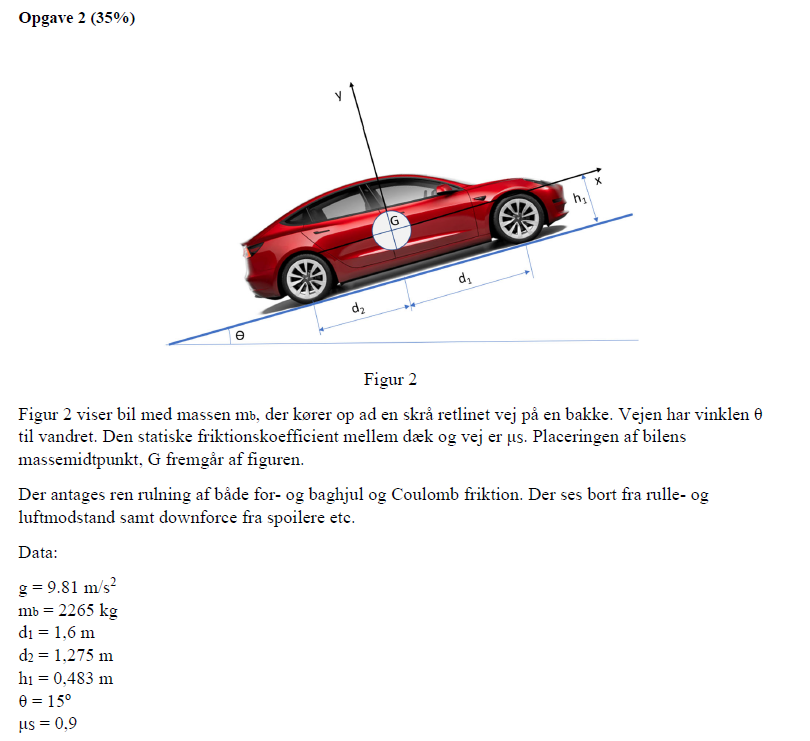

clear
% Data til opgaven
g = 9.81;  % m/s^2
mb = 2265;  % kg
d1 = 1.6;  % m
d2 = 1.275  % m

d2 = 1.2750

h1 = 0.483;  % m
theta = deg2rad(15); % Vinklen laves om til radianer da jeg syntes det nemmest at arbejde med
mu_s = 0.9;

## Opgave a)

FLD

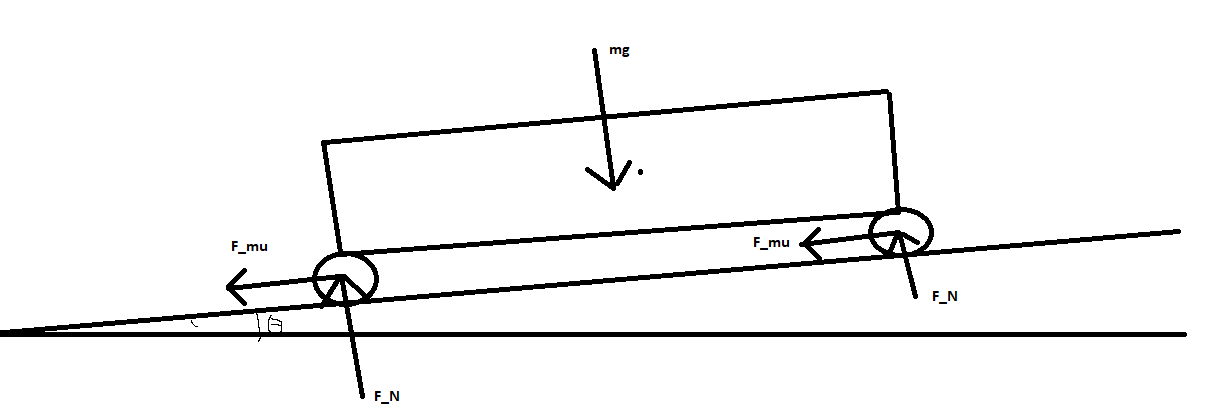

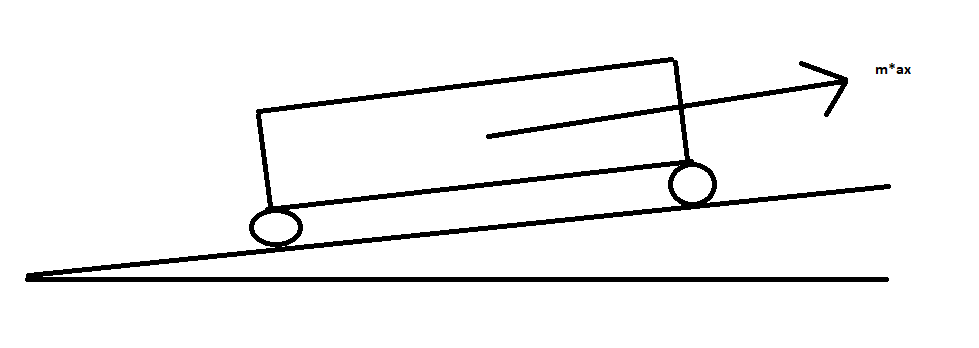

## Opgave b)


$$\sum F_x = ma_x$$



$$sin(\theta)\cdot (F_{n1} + F_{n2} - mg - \mu_s\cdot F_{n1} - \mu_s\cdot F_{n2}) = ma_x
\\
\sum F_y = 0
\\
cos(\theta)\cdot (F_{n1} + F_{n2} - mg - \mu_s\cdot F_{n1} - \mu_s\cdot F_{n2}) = ma_y
\\
\sum M_0 =  m\cdot a_{Gx} \cdot h
\\
sin(\theta)\cdot (F_{n1}\cdot d_2 + F_{n2}\cdot d_1 - mg_1 \cdot d_2 - mg_2 \cdot d_1 = m\cdot a_{Gx} \cdot h$$


## Opgave c)


$$F_{\mu1} = F_{n1}\cdot sin(\theta)\cdot \mu_s
\\
F_{\mu2} = F_{n2}\cdot sin(\theta)\cdot \mu_s$$


# Opgave 3

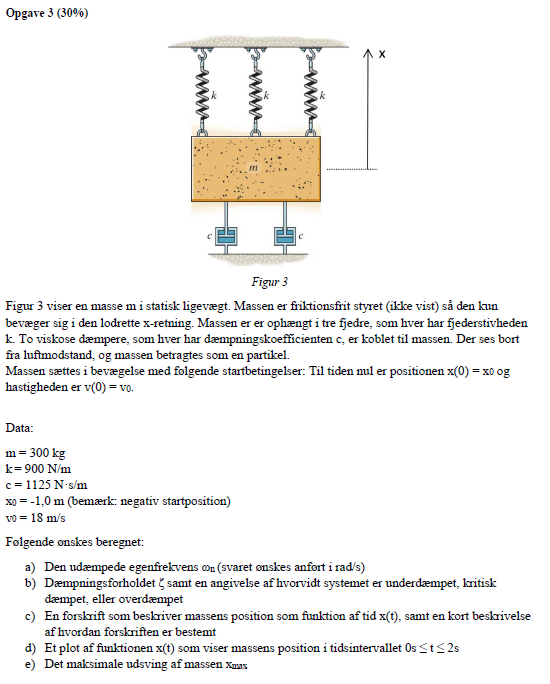

clear
% Data til opgaven

m = 300;    % kg
k = 900;    % N/m
c = 1125;   % Ns/m
x0 = -1;    % m
v0 = 18;    % m/s

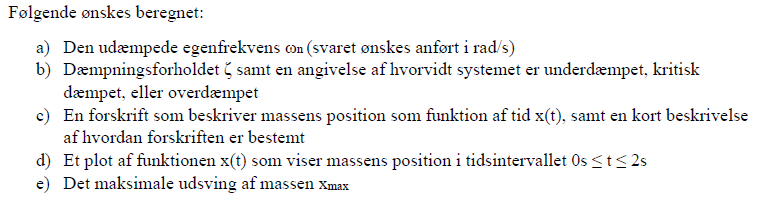

## Opgave a)

Eftersom der er 3 fjedre i en parallelkobling, ganges fjederkonstanten k med 3

u = symunit;
k = 3*k % Frem herefter er den brugte k i formler = 3*c

k = 2700


wn = sqrt(k/m)

wn = 3

Svar til opgave a

Egenfrekvensen bliver


$$\omega_n = \sqrt{\frac{k}{m}} = 3 \frac{rad}{s}$$


## Opgave b)

Igen, her er der 2 dæmpere, så dæmpningskoefficienten ganges med 2

c = 2*c; % Frem herefter er den brugte c i formler = 2*c
zeta = c/(2*m*wn)

zeta = 1.2500

Svar til opgave b

Udregning af dæmpningsforhold giver


$$\zeta = \frac{c}{2m\omega_n} = 1.25$$


Hvilken betyder der er med en overdæmpet svingning at gøre

## Opgave c)

Forklaring under

t0 = 0;
t1 = 2;


syms A1 A2 t x1

% Ligning 8/10 fra bogen benyttes og sættes lig startpositionen
x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x0

$$x\_plac\_t0 = A_{1}\,{\mathrm{e}}^{-\frac{3\,t}{2}}+A_{2}\,{\mathrm{e}}^{-6\,t}=-1$$

x_plac_t1 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x1;

% Hastigheden kommer fra at differentiere placeringsfunktionen, og sætte
% den lig starthastigheden
x_vel = diff(lhs(x_plac_t0), t) == v0

$$x\_vel = -\frac{3\,A_{1}\,{\mathrm{e}}^{-\frac{3\,t}{2}}}{2}-6\,A_{2}\,{\mathrm{e}}^{-6\,t}=18$$


% Ligningerne og de ukendte løses
eqs = [x_plac_t0, x_vel];
vars = [A1, A2];

sols = solve(eqs, vars)

sols = struct with fields:
    A1: (8*exp((3*t)/2))/3
    A2: -(11*exp(6*t))/3



% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne til
% tiden t0

A1_ny = vpa(subs(sols.A1, t, t0),4)

$$A1\_ny = 2.667$$

A2_ny = vpa(subs(sols.A2, t, t0),4)

$$A2\_ny = -3.667$$


% Funktionen præsenteres
funktion = vpa(subs(lhs(x_plac_t1), [A1, A2], [A1_ny, A2_ny]),4)

$$funktion = 2.667\,{\mathrm{e}}^{-1.5\,t}-3.667\,{\mathrm{e}}^{-6.0\,t}$$

Svar til opgave c)

Da det er fundet at der er med en overdæmpet funktion at gøre, bruges formel 8/10 i bogen (her er den kaldt $x_{plac, t_0}$), og der løses for konstanterne A1 og A2.

De tidligere udregnede værdier for 


$$\zeta = 1.25$$



$$\omega_n = 3$$


Er brugt i formlen.

Når der er løst for A1 og A2, som hhv er


$$A_1 = 2,667$$



$$A_2 = -3,667$$


Indsættes de i startformlen 8/10, og følgende funktion fås


$$x(t) = 2,667e^{1,5\cdot t} - 3,667e^{-6\cdot t}$$


## Opgave d)

Funktionen plottes i det givne interval for tiden 0 til 2 sekunder

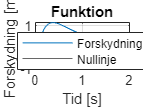

syms func(t)
xp = x0;

func(t) = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*t);

fplot(func(t), [t0,t1], "DisplayName", "Forskydning"), xlabel("Tid [s]"), ylabel("Forskydning [m]"), grid()
yline(t0, "DisplayName", "Nullinje")

title("Funktion");

legend("Location","best")

Hvor det ses at til t = 0 er forskydningen x(0) = -1, som det også var opgivet i opgaven

## Opgave e)

Det maksimale udsving af massen findes

tlin = linspace(0, 2, 1000);

xmax = A1_ny*exp((-zeta + sqrt(zeta^2 - 1))*wn*tlin) + A2_ny*exp((-zeta-sqrt(zeta^2-1))*wn*tlin);

[xmax, I] = max(xmax);

maks = vpa(xmax,5)

$$maks = 1.133$$

tid = vpa(tlin(I),4)

$$tid = 0.3784$$

I funktionen fundet i opgaven c) er der søgt efter en maksimalværdi, som er fundet til 


$$x_{max} = 1.133m$$


til tiden


$$t = 0.3784s$$


Det er det maksimale udsving fra startpositionen